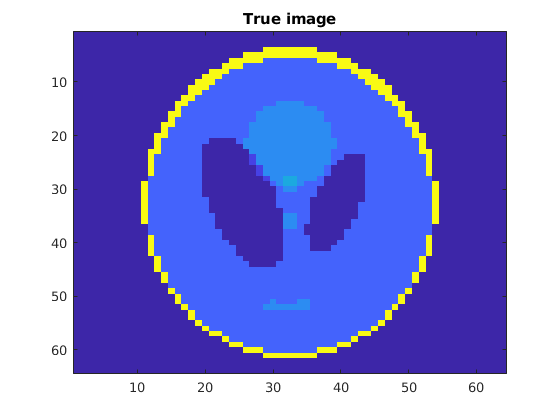

clc;
clear;
close all;
rng('default');

N = 64;          % Image is N-by-N pixels
theta = 0:2:178; % projection angles
p = 90;          % Number of rays for each angle

% Assemble the X-ray tomography matrix, the true data, and true image
[K, d, m_true] = paralleltomo(N, theta, p);

figure; imagesc(reshape(m_true, N, N));
title('True image');

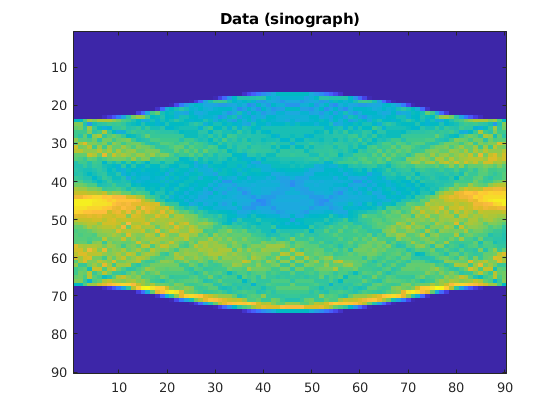

figure; imagesc(reshape(d, p, length(theta)));
title('Data (sinograph)');

% Remove possibly 0 rows from K and d (get index as well)
[K, d, idx] = purge_rows(K, d);

% A) Reconstruct m using ART. Report convergence history (i.e. residual and
% error norms at each iteration)

% precompute the norm of each row
K_norms = full(sum(K.^2,2));

% run ART (See ART.cpp file)
tic;
m_art = ART(K',K_norms,d);

Copying data over to C data types...
Iteration #: 0
Iteration #: 1
Iteration #: 2
Iteration #: 3
Iteration #: 4
Iteration #: 5
Iteration #: 6
Iteration #: 7
Iteration #: 8
Iteration #: 9
Iteration #: 10
Iteration #: 11
Iteration #: 12
Iteration #: 13
Iteration #: 14
Iteration #: 15
Iteration #: 16
Iteration #: 17
Iteration #: 18
Iteration #: 19
Iteration #: 20
Iteration #: 21
Iteration #: 22
Iteration #: 23
Iteration #: 24
Iteration #: 25
Iteration #: 26
Iteration #: 27
Iteration #: 28
Iteration #: 29
Iteration #: 30
Iteration #: 31
Iteration #: 32
Iteration #: 33
Iteration #: 34
Iteration #: 35
Iteration #: 36
Iteration #: 37
Iteration #: 38
Iteration #: 39
Iteration #: 40
Iteration #: 41
Iteration #: 42
Iteration #: 43
Iteration #: 44
Iteration #: 45
Iteration #: 46
Iteration #: 47
Iteration #: 48
Iteration #: 49
Iteration #: 50
Iteration #: 51
Iteration #: 52
Iteration #: 53
Iteration #: 54
Iteration #: 55
Iteration #: 56
Iteration #: 57
Iteration #: 58
Iteration #: 59
Iteration #: 

toc;

Elapsed time is 9.562372 seconds.


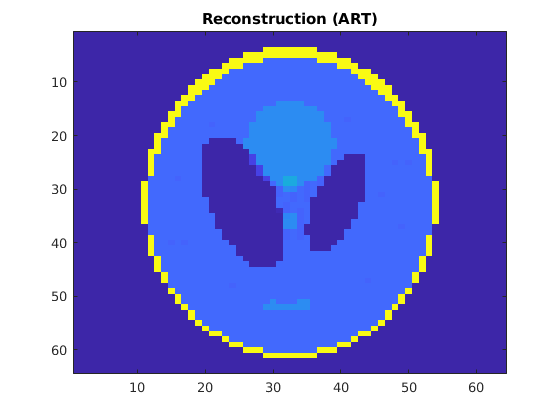

% calculate residual and error
residual_art = sqrt(sum((repmat(d,1,1000) - K*m_art).^2,1));
error_art = sqrt(sum((repmat(m_true,1,1000) - m_art).^2,1));

% plot stuff
figure; imagesc(reshape(m_art(:,1000),64,64)); title('Reconstruction (ART)');

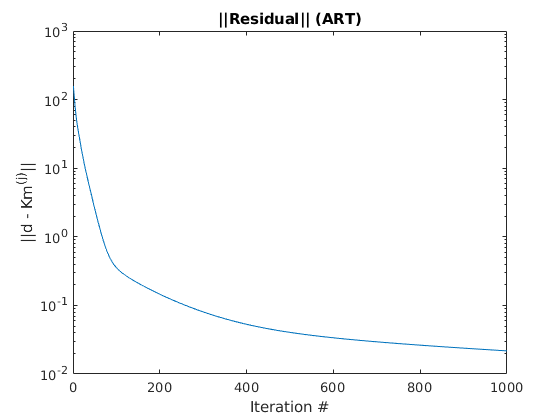

figure; semilogy(1:1000,residual_art); title('||Residual|| (ART)');
xlabel('Iteration #'); ylabel('||d - Km^{(j)}||');

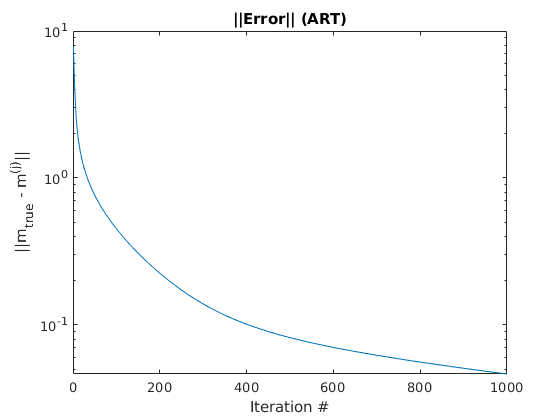

figure; semilogy(1:1000,error_art); title('||Error|| (ART)');
xlabel('Iteration #'); ylabel('||m_{true} - m^{(j)}||');

% B) Reconstruct m using SART. Report convergence history and compare with
% ART

% run SART (See SART.cpp file)
tic;
m_sart = SART(K',K_norms,d,idx);

Copying data over to C data types...
Iteration #: 0
Iteration #: 1
Iteration #: 2
Iteration #: 3
Iteration #: 4
Iteration #: 5
Iteration #: 6
Iteration #: 7
Iteration #: 8
Iteration #: 9
Iteration #: 10
Iteration #: 11
Iteration #: 12
Iteration #: 13
Iteration #: 14
Iteration #: 15
Iteration #: 16
Iteration #: 17
Iteration #: 18
Iteration #: 19
Iteration #: 20
Iteration #: 21
Iteration #: 22
Iteration #: 23
Iteration #: 24
Iteration #: 25
Iteration #: 26
Iteration #: 27
Iteration #: 28
Iteration #: 29
Iteration #: 30
Iteration #: 31
Iteration #: 32
Iteration #: 33
Iteration #: 34
Iteration #: 35
Iteration #: 36
Iteration #: 37
Iteration #: 38
Iteration #: 39
Iteration #: 40
Iteration #: 41
Iteration #: 42
Iteration #: 43
Iteration #: 44
Iteration #: 45
Iteration #: 46
Iteration #: 47
Iteration #: 48
Iteration #: 49
Iteration #: 50
Iteration #: 51
Iteration #: 52
Iteration #: 53
Iteration #: 54
Iteration #: 55
Iteration #: 56
Iteration #: 57
Iteration #: 58
Iteration #: 59
Iteration #: 

toc;

Elapsed time is 10.076522 seconds.


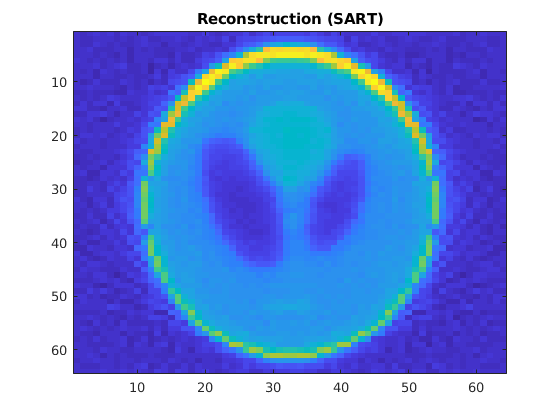

% calculate residual and error
residual_sart = sqrt(sum((repmat(d,1,1000) - K*m_sart).^2,1));
error_sart = sqrt(sum((repmat(m_true,1,1000) - m_sart).^2,1));

% plot stuff
figure; imagesc(reshape(m_sart(:,1000),64,64)); title('Reconstruction (SART)');

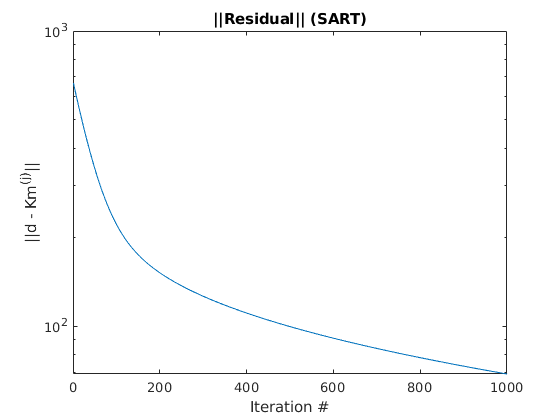

figure; semilogy(1:1000,residual_sart); title('||Residual|| (SART)');
xlabel('Iteration #'); ylabel('||d - Km^{(j)}||');

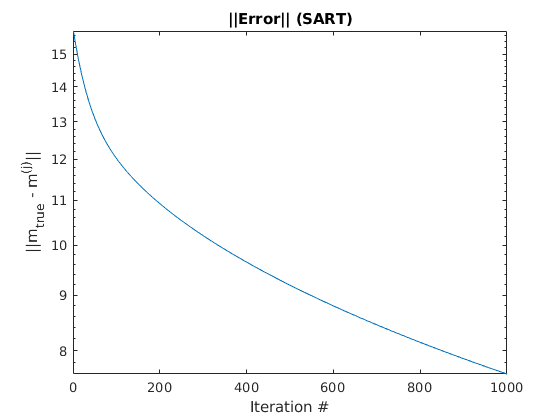

figure; semilogy(1:1000,error_sart); title('||Error|| (SART)');
xlabel('Iteration #'); ylabel('||m_{true} - m^{(j)}||');

% C) Reconstruct m using SIRT. Report convergence history and compare with
% ART and SART

% run SIRT (See SIRT.cpp file)
tic;
m_sirt = SIRT(K',K_norms,d);

Copying data over to C data types...
Iteration #: 0
Iteration #: 1
Iteration #: 2
Iteration #: 3
Iteration #: 4
Iteration #: 5
Iteration #: 6
Iteration #: 7
Iteration #: 8
Iteration #: 9
Iteration #: 10
Iteration #: 11
Iteration #: 12
Iteration #: 13
Iteration #: 14
Iteration #: 15
Iteration #: 16
Iteration #: 17
Iteration #: 18
Iteration #: 19
Iteration #: 20
Iteration #: 21
Iteration #: 22
Iteration #: 23
Iteration #: 24
Iteration #: 25
Iteration #: 26
Iteration #: 27
Iteration #: 28
Iteration #: 29
Iteration #: 30
Iteration #: 31
Iteration #: 32
Iteration #: 33
Iteration #: 34
Iteration #: 35
Iteration #: 36
Iteration #: 37
Iteration #: 38
Iteration #: 39
Iteration #: 40
Iteration #: 41
Iteration #: 42
Iteration #: 43
Iteration #: 44
Iteration #: 45
Iteration #: 46
Iteration #: 47
Iteration #: 48
Iteration #: 49
Iteration #: 50
Iteration #: 51
Iteration #: 52
Iteration #: 53
Iteration #: 54
Iteration #: 55
Iteration #: 56
Iteration #: 57
Iteration #: 58
Iteration #: 59
Iteration #: 

toc;

Elapsed time is 9.815371 seconds.


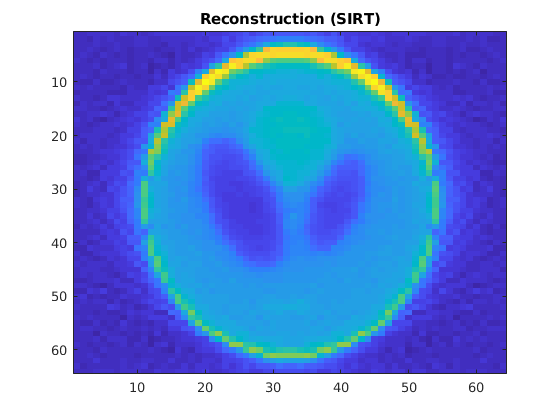

% calculate residual and error
residual_sirt = sqrt(sum((repmat(d,1,1000) - K*m_sirt).^2,1));
error_sirt = sqrt(sum((repmat(m_true,1,1000) - m_sirt).^2,1));

% plot stuff
figure; imagesc(reshape(m_sirt(:,1000),64,64)); title('Reconstruction (SIRT)');

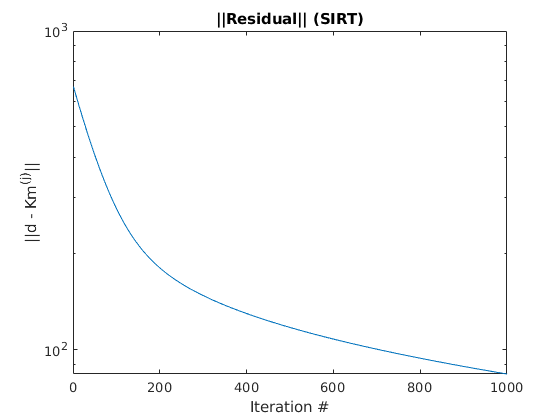

figure; semilogy(1:1000,residual_sirt); title('||Residual|| (SIRT)');
xlabel('Iteration #'); ylabel('||d - Km^{(j)}||');

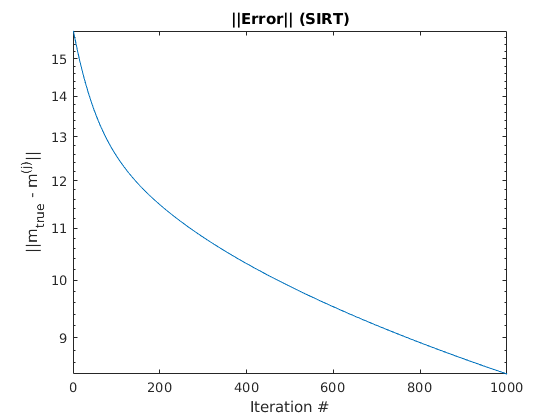

figure; semilogy(1:1000,error_sirt); title('||Error|| (SIRT)');
xlabel('Iteration #'); ylabel('||m_{true} - m^{(j)}||');

% D) Consider the case with noisy data. Reconstruct m using ART, SART,
% SIRT. Report convergence history and discuss what you observed.
noise_level = 0.01; % noise level.
noise_std = noise_level*norm(d,'inf');
dn = d + noise_std*randn(size(d));

% Run ART, SART, and SIRT
tic;
mn_art = ART(K',K_norms,dn);

Copying data over to C data types...
Iteration #: 0
Iteration #: 1
Iteration #: 2
Iteration #: 3
Iteration #: 4
Iteration #: 5
Iteration #: 6
Iteration #: 7
Iteration #: 8
Iteration #: 9
Iteration #: 10
Iteration #: 11
Iteration #: 12
Iteration #: 13
Iteration #: 14
Iteration #: 15
Iteration #: 16
Iteration #: 17
Iteration #: 18
Iteration #: 19
Iteration #: 20
Iteration #: 21
Iteration #: 22
Iteration #: 23
Iteration #: 24
Iteration #: 25
Iteration #: 26
Iteration #: 27
Iteration #: 28
Iteration #: 29
Iteration #: 30
Iteration #: 31
Iteration #: 32
Iteration #: 33
Iteration #: 34
Iteration #: 35
Iteration #: 36
Iteration #: 37
Iteration #: 38
Iteration #: 39
Iteration #: 40
Iteration #: 41
Iteration #: 42
Iteration #: 43
Iteration #: 44
Iteration #: 45
Iteration #: 46
Iteration #: 47
Iteration #: 48
Iteration #: 49
Iteration #: 50
Iteration #: 51
Iteration #: 52
Iteration #: 53
Iteration #: 54
Iteration #: 55
Iteration #: 56
Iteration #: 57
Iteration #: 58
Iteration #: 59
Iteration #: 

mn_sart = SART(K',K_norms,dn,idx);

Copying data over to C data types...
Iteration #: 0
Iteration #: 1
Iteration #: 2
Iteration #: 3
Iteration #: 4
Iteration #: 5
Iteration #: 6
Iteration #: 7
Iteration #: 8
Iteration #: 9
Iteration #: 10
Iteration #: 11
Iteration #: 12
Iteration #: 13
Iteration #: 14
Iteration #: 15
Iteration #: 16
Iteration #: 17
Iteration #: 18
Iteration #: 19
Iteration #: 20
Iteration #: 21
Iteration #: 22
Iteration #: 23
Iteration #: 24
Iteration #: 25
Iteration #: 26
Iteration #: 27
Iteration #: 28
Iteration #: 29
Iteration #: 30
Iteration #: 31
Iteration #: 32
Iteration #: 33
Iteration #: 34
Iteration #: 35
Iteration #: 36
Iteration #: 37
Iteration #: 38
Iteration #: 39
Iteration #: 40
Iteration #: 41
Iteration #: 42
Iteration #: 43
Iteration #: 44
Iteration #: 45
Iteration #: 46
Iteration #: 47
Iteration #: 48
Iteration #: 49
Iteration #: 50
Iteration #: 51
Iteration #: 52
Iteration #: 53
Iteration #: 54
Iteration #: 55
Iteration #: 56
Iteration #: 57
Iteration #: 58
Iteration #: 59
Iteration #: 

mn_sirt = SIRT(K',K_norms,dn);

Copying data over to C data types...
Iteration #: 0
Iteration #: 1
Iteration #: 2
Iteration #: 3
Iteration #: 4
Iteration #: 5
Iteration #: 6
Iteration #: 7
Iteration #: 8
Iteration #: 9
Iteration #: 10
Iteration #: 11
Iteration #: 12
Iteration #: 13
Iteration #: 14
Iteration #: 15
Iteration #: 16
Iteration #: 17
Iteration #: 18
Iteration #: 19
Iteration #: 20
Iteration #: 21
Iteration #: 22
Iteration #: 23
Iteration #: 24
Iteration #: 25
Iteration #: 26
Iteration #: 27
Iteration #: 28
Iteration #: 29
Iteration #: 30
Iteration #: 31
Iteration #: 32
Iteration #: 33
Iteration #: 34
Iteration #: 35
Iteration #: 36
Iteration #: 37
Iteration #: 38
Iteration #: 39
Iteration #: 40
Iteration #: 41
Iteration #: 42
Iteration #: 43
Iteration #: 44
Iteration #: 45
Iteration #: 46
Iteration #: 47
Iteration #: 48
Iteration #: 49
Iteration #: 50
Iteration #: 51
Iteration #: 52
Iteration #: 53
Iteration #: 54
Iteration #: 55
Iteration #: 56
Iteration #: 57
Iteration #: 58
Iteration #: 59
Iteration #: 

toc;

Elapsed time is 30.460995 seconds.


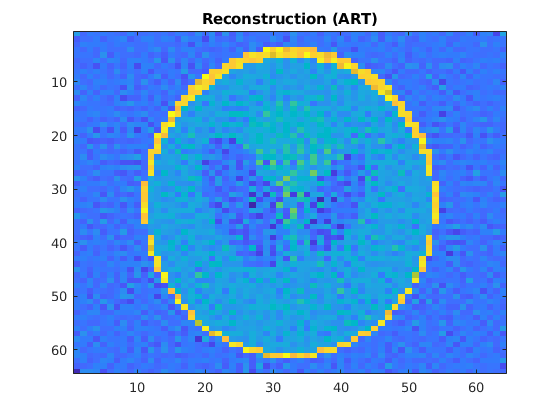

% calculate residuals and errors
residualn_art = sqrt(sum((repmat(dn,1,1000) - K*mn_art).^2,1));
errorn_art = sqrt(sum((repmat(m_true,1,1000) - mn_art).^2,1));
residualn_sart = sqrt(sum((repmat(dn,1,1000) - K*mn_sart).^2,1));
errorn_sart = sqrt(sum((repmat(m_true,1,1000) - mn_sart).^2,1));
residualn_sirt = sqrt(sum((repmat(dn,1,1000) - K*mn_sirt).^2,1));
errorn_sirt = sqrt(sum((repmat(m_true,1,1000) - mn_sirt).^2,1));

% plot stuff
figure; imagesc(reshape(mn_art(:,1000),64,64)); title('Reconstruction (ART)');

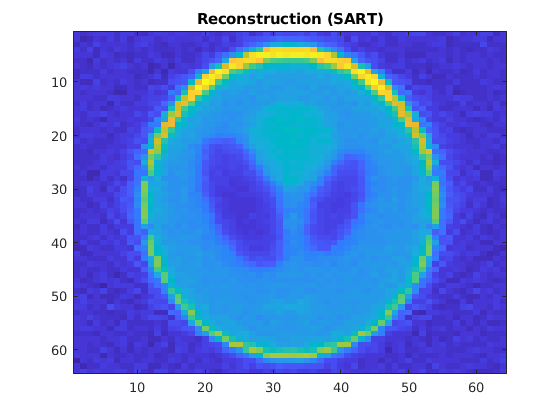

figure; imagesc(reshape(mn_sart(:,1000),64,64)); title('Reconstruction (SART)');

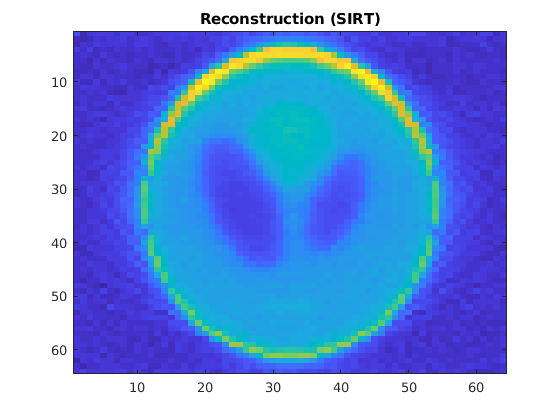

figure; imagesc(reshape(mn_sirt(:,1000),64,64)); title('Reconstruction (SIRT)');

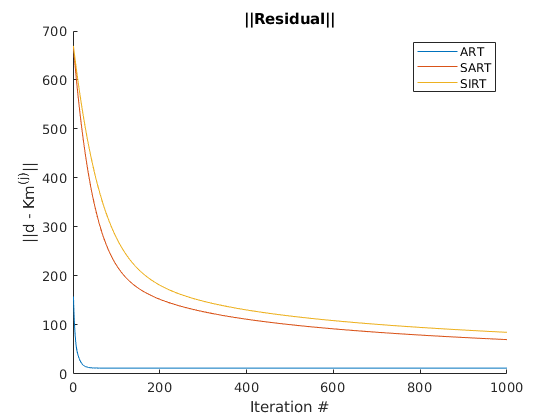

figure; title('||Residual||'); hold on;
semilogy(1:1000,residualn_art);
semilogy(1:1000,residualn_sart);
semilogy(1:1000,residualn_sirt);
xlabel('Iteration #'); ylabel('||d - Km^{(j)}||');
legend('ART','SART','SIRT');
hold off;

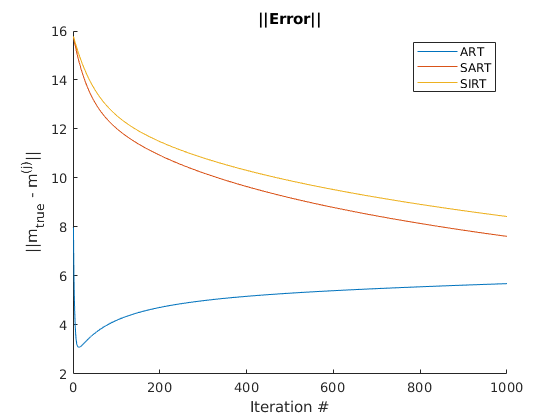

figure; title('||Error||'); hold on;
semilogy(1:1000,errorn_art);
semilogy(1:1000,errorn_sart);
semilogy(1:1000,errorn_sirt);
xlabel('Iteration #'); ylabel('||m_{true} - m^{(j)}||');
legend('ART','SART','SIRT');
hold off;

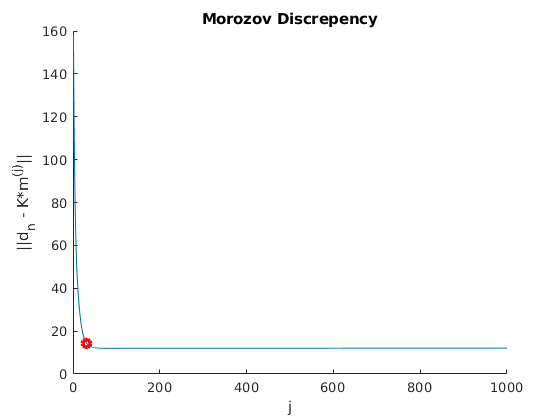

% E) Implement Morozov discrepancy principle as stopping criterion for ART

% get norm of noise data
delta = norm(noise_std*randn(size(d)));

% find morozov alpha through bisection method
a = 1000;
b = 1;
resid_a = residualn_art(a);
resid_b = residualn_art(b);
iterations = 20;
for i=1:iterations
    % find midpoint
    midpoint = round((a + b)/2);
    
    % get residual at midpoint
    resid_mid = residualn_art(midpoint);
    
    % check current intervals and assign new intervals
    if resid_a <= delta && delta <= resid_mid
       b = midpoint;
        resid_b = residualn_art(b);
    elseif resid_mid <= delta && delta <= resid_b
        a = midpoint;
        resid_a = residualn_art(a);
    else
        error(['Optimal j outside bounds! \' ...
            'Increase initial j search range.'])
    end
end
% get optimal morozov j and resid
j_opt = round((a + b)/2);
resid_opt = residualn_art(j_opt);

% plot morozov discrepency
figure; hold on;
semilogy(1:1000,residualn_art);
semilogy(j_opt, resid_opt, 'ro', 'Linewidth', 3);
title('Morozov Discrepency');
xlabel('j'); ylabel('||d_{n} - K*m^{(j)}||');
hold off;

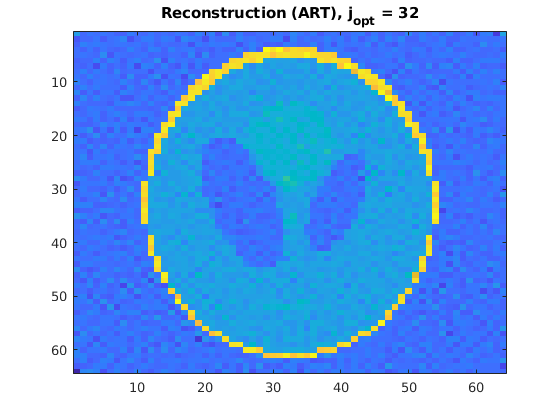

% plot image
figure; imagesc(reshape(mn_art(:,j_opt),64,64)); title(['Reconstruction (ART), j_{opt} = ' num2str(j_opt)]);